%% Import data from text file
% Script for importing data from the following text file:
%
%    filename: D:\scope_0.csv
%
% Auto-generated by MATLAB on 17-Feb-2023 15:45:16

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "FrequencyHz", "AmplitudeVpp", "GaindB", "Phase"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scope = readtable("D:\scope_0.csv", opts);


%% Clear temporary variables
clear opts




## Full Reset Command

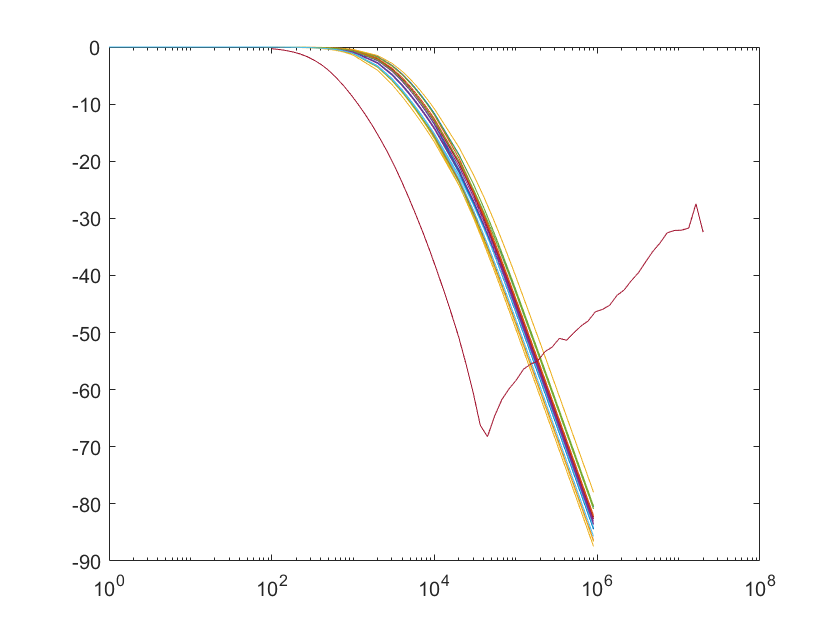


x= scope.FrequencyHz;
y=scope.GaindB;

R1 = 44.51;
R2 = 374.43;
C1 = 1.04*10^-6;
C2 = 1.04*10^-6;
b = [1;0;0];

QX = [R1 R2 C1 C2];
r = [1 2 3 4 5 6 7 8 9];
w = [r (10*r) ((1e2)*r) ((1e3)*r) ((1e4)*r) ((1e5)*r)];

num = 20;
for s=1:num
    Q = variation(QX); 
    G = zeros(3,3);
    C = zeros(3,3);
    G(1,1) = 1;
    G(2,1) = (-1/Q(1)); % No G(2,1)
    G(2,2) = 1/Q(1)+1/Q(2); 
    G(2,3) = (-1/Q(2));
    G(3,2) = (-1/Q(2));
    G(3,3) = (1/Q(2)); % you had interchanged this part, No C(1,2)
    C(2,2) = Q(3); 
    C(3,3) = Q(4);

for K = 1:length(w)
    Omega = w(K);
    A = G + (j*Omega*C);
    x = A\b;
    mag(:,K) = abs(x);
end

V3 = mag(3,:); % chaged from V3= mag(3,1:length(w)+1);
x= scope.FrequencyHz;
y=scope.GaindB;

VC2(s,:) = V3;
FX = 20*log10(V3);
 F(s,:) = FX;
 semilogx(w,F);
 hold on;
 semilogx(x,y)
 grid
 hold off
end

grid

function Q = variation(R)
m = length(R);
g = ones(1,m) + 0.5*rand(1,m);
Q = 0.8*(R.*g);
end